# Equivalent Rotational Mass

% Created by: Giacomo Mastroddi, September 2023
% Images by: Alexandr Ebnöther, September 2023
clear; close all;

par = get_car_param();

## Data from images

#### Image 1: Front Rotating Mass

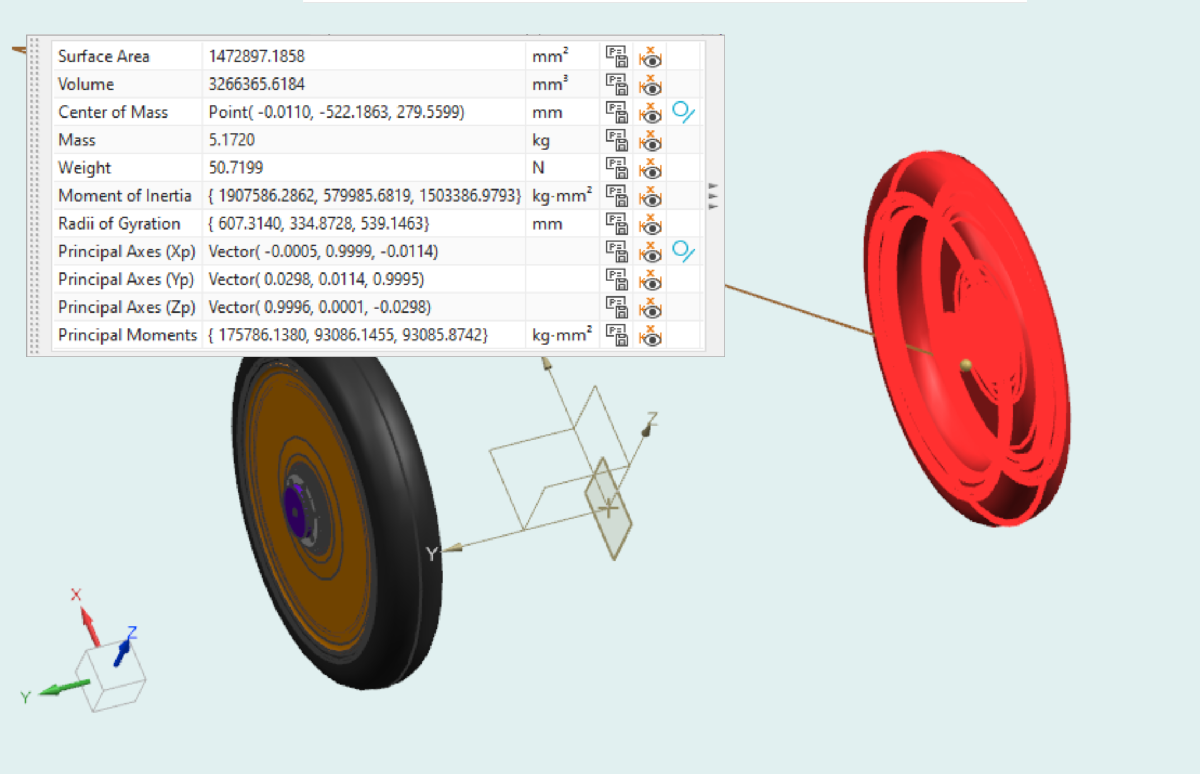

% Moment of Inertia (kg-mm^2)
MOI_1 = [1907586.2862, 579985.6819, 1503386.9793];
% Principal Moments (kg-mm^2)
PrincipalMoments_1 = [175786.1380, 93086.1455, 93085.8742];
% Principal Axes Vectors
Xp_1 = [-0.0005, 0.9999, -0.0114];
Yp_1 = [0.0298, 0.0114, 0.9995];
Zp_1 = [0.9996, 0.0001, -0.0298];

#### Image 2: Rear Rotating Mass (only tires / rims, no brake disc, no motor)

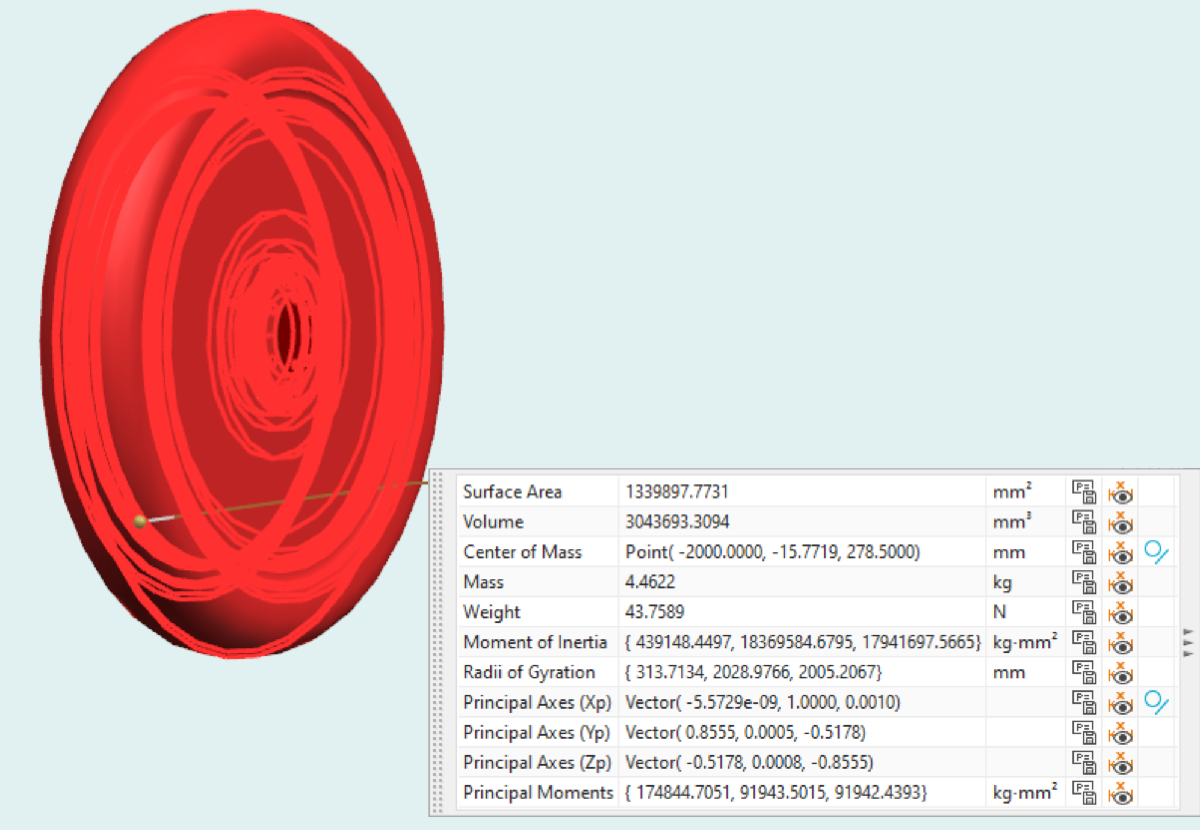

% Moment of Inertia (kg-mm^2)
MOI_2 = [439148.4497, 18369584.6795, 17941697.5665];
% Principal Moments (kg-mm^2)
PrincipalMoments_2 = [174844.7051, 91943.5015, 91942.4393];
% Principal Axes Vectors
Xp_2 = [-5.5729e-09, 1.0000, 0.0010];
Yp_2 = [0.8555, 0.0005, -0.5178];
Zp_2 = [-0.5178, 0.0008, -0.8555];

#### Image 3: Rear Rotating Mass (complete, part of motor)

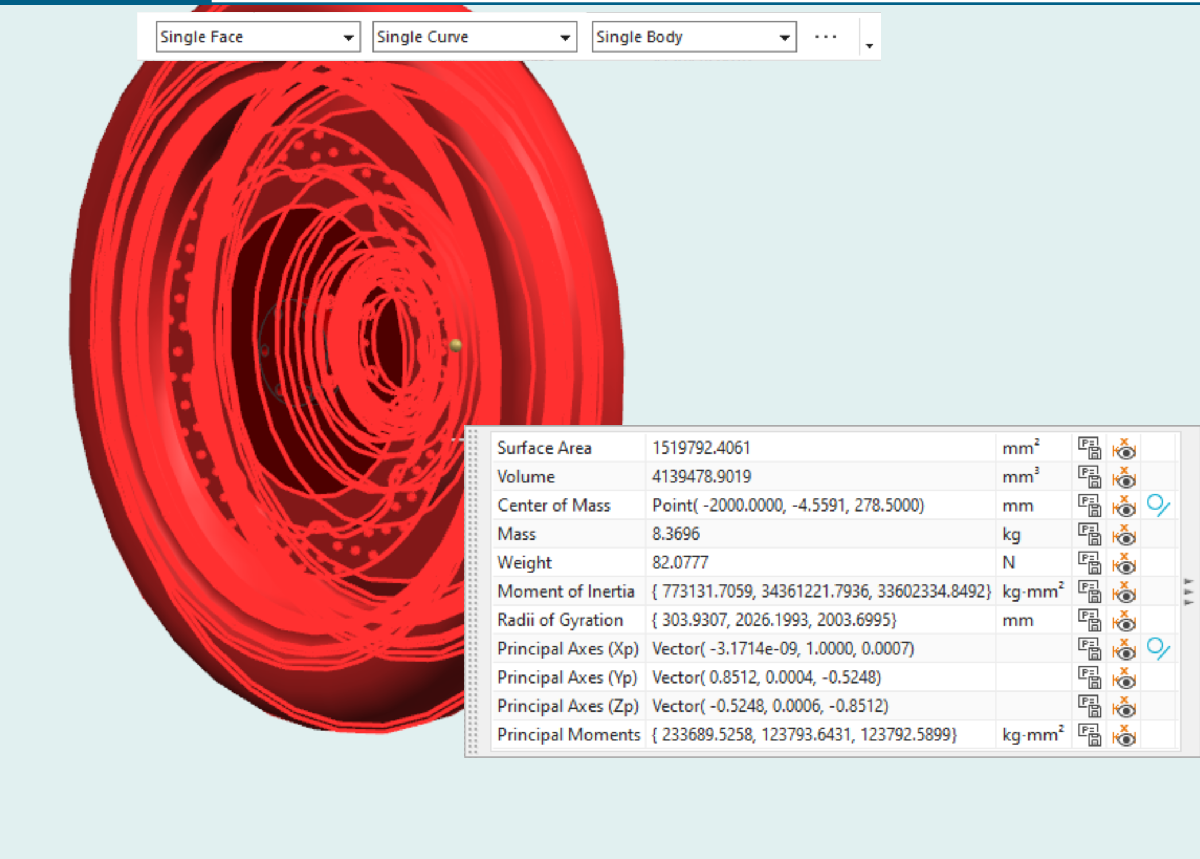

% Moment of Inertia (kg-mm^2)
MOI_3 = [773131.7059, 34361221.7936, 33602334.8492];
% Principal Moments (kg-mm^2)
PrincipalMoments_3 = [233689.5258, 123793.6431, 123792.5899];
% Principal Axes Vectors
Xp_3 = [-3.1714e-09, 1.0000, 0.0007];
Yp_3 = [0.8512, 0.0004, -0.5248];
Zp_3 = [-0.5248, 0.0006, -0.8512];

#### Image 4: Rear Rotating Mass (complete, whole motor)

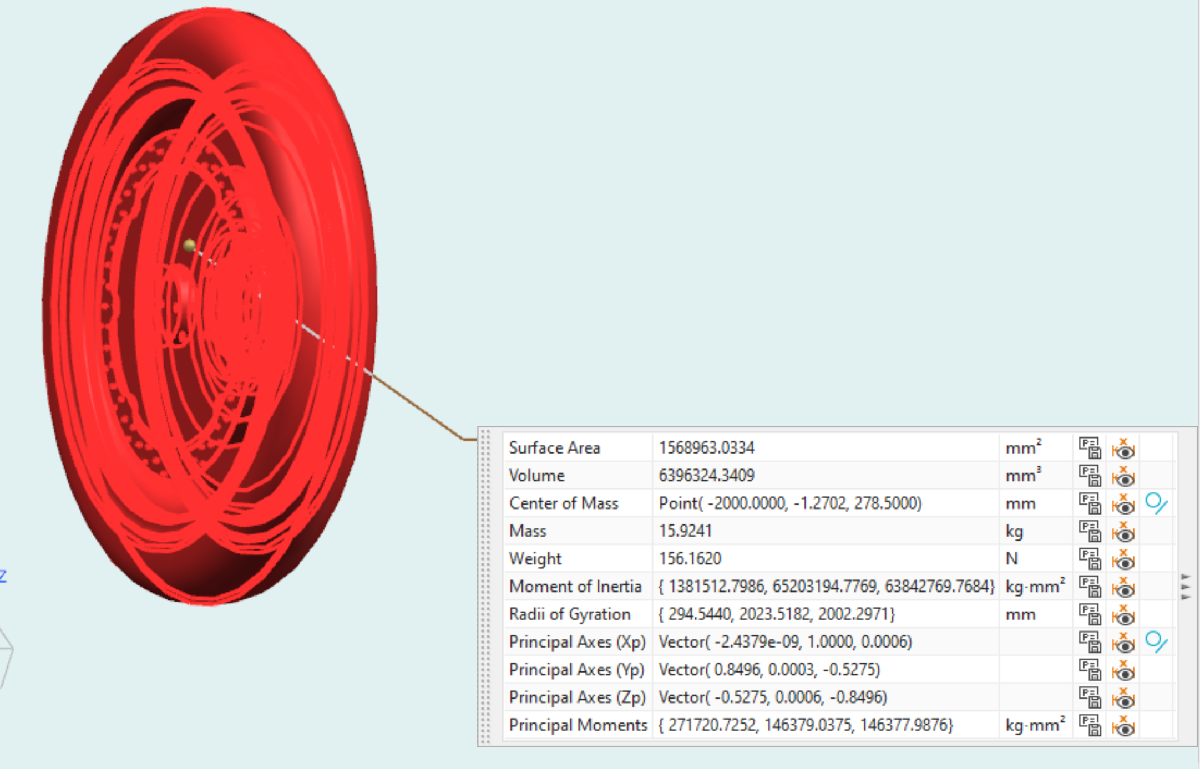

% Moment of Inertia (kg-mm^2)
MOI_4 = [1381512.7986, 65203194.7769, 63842769.7684];
% Principal Moments (kg-mm^2)
PrincipalMoments_4 = [271720.7252, 146379.0375, 146377.9876];
% Principal Axes Vectors
Xp_4 = [-2.4379e-09, 1.0000, 0.0006];
Yp_4 = [0.8496, 0.0003, -0.5275];
Zp_4 = [-0.5275, 0.0006, -0.8496];

## Calculations

Convert wheel radius in mm

r_w_mm = par.r_w * 1e3; % in mm

Using the principal moment around principal axis X_p: the y component is almost 1. Not using the y component of MOI, because the y-axis in CAD is far away and the values are huge

EqMass1 = PrincipalMoments_1(1) / r_w_mm^2;
fprintf("Eq mass 1: %.2f kg", EqMass1)

Eq mass 1: 2.27 kg

EqMass2 = PrincipalMoments_2(1) / r_w_mm^2;
fprintf("Eq mass 2: %.2f kg", EqMass2)

Eq mass 2: 2.25 kg

EqMass3 = PrincipalMoments_3(1) / r_w_mm^2;
fprintf("Eq mass 3: %.2f kg", EqMass3)

Eq mass 3: 3.01 kg

EqMass4 = PrincipalMoments_4(1) / r_w_mm^2;
fprintf("Eq mass 4: %.2f kg", EqMass4)

Eq mass 4: 3.50 kg

We take the worst case, namely the heaviest 4

EqMassTot = EqMass1 * 2 + EqMass4;
fprintf("Tot eq mass: %.2f kg", EqMassTot)

Tot eq mass: 8.04 kg

save("tot_eq_rot_mass", "EqMassTot")